# Manipolabilità del robot RR planare

## Robot RR planare

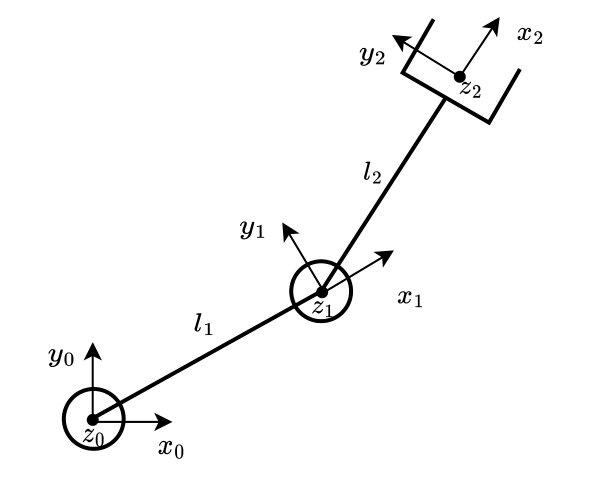

clear
clc
syms q1 q2 l1 l2 real
l1 = 1;
l2 = 1;
DHRRplanare = [l1, 0, 0, q1;
               l2, 0, 0, q2]

$$DHRRplanare = \left(\begin{array}{cccc} 1 & 0 & 0 & q_{1}\\ 1 & 0 & 0 & q_{2} \end{array}\right)$$

tList = cinDirDH(DHRRplanare);
T03 = tList{3}

$$T03 = \left(\begin{array}{cccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & 0 & \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & 0 & \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

r = T03(1:2, 4);
J = [diff(r(1), q1), diff(r(1), q2);
     diff(r(2), q1), diff(r(2), q2)]

$$J = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

## Elissoide di manipolabilità

w = simplify(sqrt(det(J*J.')))

$$w = \left|\sin\left(q_{2}\right)\right|$$

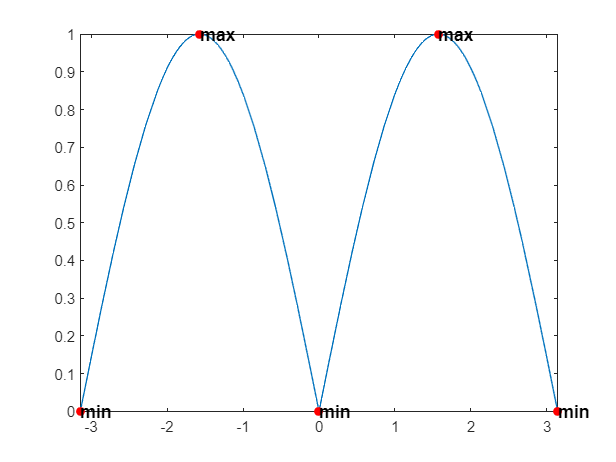

figure
fplot(w,[-pi, pi])
hold on
maxManConf = [-pi/2, pi/2];
minManConf = [-pi, 0, pi];
for i=1:size(maxManConf, 2)
    q_2 = maxManConf(i);
    scatter(q_2, subs(w, q2, q_2), 'filled', 'MarkerFaceColor', 'r');
    text(q_2, subs(w, q2, q_2), "max", 'FontSize', 12, 'FontWeight', 'bold');
end
for i=1:size(minManConf, 2)
    q_2 = minManConf(i);
    scatter(q_2, subs(w, q2, q_2), 'filled', 'MarkerFaceColor', 'r');
    text(q_2, subs(w, q2, q_2), "min", 'FontSize', 12, 'FontWeight', 'bold');
end
hold off

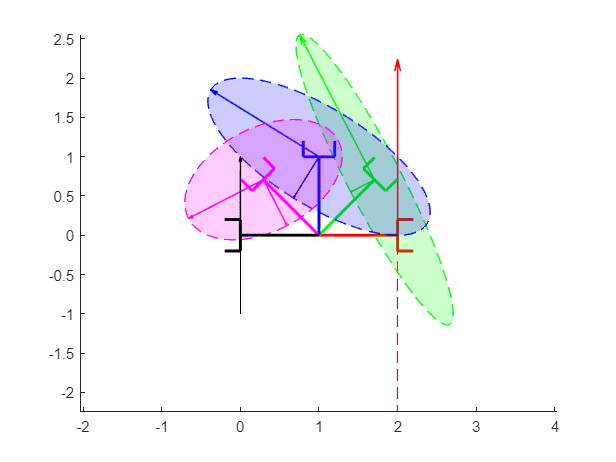

q = linspace(0, pi, 5);
q_1 = 0;
colors = ['r', 'g', 'b', 'm', 'k'];

figure   
for i=1:size(q,2)

    q_2 = q(i);
    center = subs(r, [q1, q2], [q_1, q_2]);
    Jq = double(subs(J, [q1, q2], [q_1, q_2]));
    drawManEllipse(Jq, center, colors(i));

    drawPlanarRobot([1, 1], [q_1, q_2], colors(i))
    axis equal
end